# Model comparisons 

During this session, we will discuss how to select a statistical model from a set of candidate models given the data. This is also called **model comparison**. In order to choose a model, you can either use a pre-existing data set to fit a model, or design a study in such a way that the collected data is well suited to the problem of model selection. Model selection techniques can be considered as estimators of some physical quantity, such as the probability of the model producing the given data. The *bias *and *variance* are both important measures of the quality of this estimator. 

We will discuss the following topics:

- reasons for model-fitting your data and selecting an appropriate model 

- comparing models with different number of parameters

- dealing with multiple comparisons 

- fitting your data to different models and evaluating individual model fits

- comparing the model fits to find the best model (AIC, BIC, cross-validation)

## Reasons for Model-fitting

Model fitting is a procedure that takes three steps:             

- You need a function that takes in a set of parameters and returns a predicted data set.

- You need an '*error function*' that provides a number representing the difference between your data and the model's prediction for any given set of model parameters. This is usually  either the **sums of squared error** (SSE) or **maximum likelihood**. 

- You need to find the parameters that minimize this difference. 

Although you have a model that fits your data perfectly, it might not be telling what is actually going on in the system. The reasoning behind choosing a model, and why you use certain parameters, is more important than that the model actually fits your data very well.

## Different number of parameters

- Testing HOW the system works - you have a model and using the model to help explain the data to gain deeper insights into the mechanisms.

- Choosing the right model and a correct set of parameters critically depends on what you know about the system. Examples are visual/motor tuning, reinforcement/learning, attention/normalization, etc.

- A famous scientist once said: "if you have 9 or more parameters, you can fit anything". More parameters always gives a better fit of your data. However, having too many parameters make your model fit meaningless. Therefore, it is important to keep only the critical parameters and test the signifcant necessity of additional parameters (comparing a model with N parameters to model with N-1 parameters). 

- The best model is a simpel model that can explain your data the best.

## Dealing with Multiple Comparisons

If you run a statistical test for multiple times, you are more likely to find a false positive result (false positive rate), which is called the [multiple comparison problem](https://en.wikipedia.org/wiki/Multiple_comparisons_problem). Multiple comparisons arise when a statistical analysis involves multiple statistical tests, each of which has a potential to produce a "discovery." Failure to compensate for multiple comparisons can have important real-world consequences. There are many ways to get around this problem:

- [Bonferroni correction: ](https://en.wikipedia.org/wiki/Bonferroni_correction)most conservative, but also most well known. Bonferonni correction is part of the [family-wise error correction](https://en.wikipedia.org/wiki/Family-wise_error_rate), which is ithe probability of making one or more false discoveries ([type I errors](https://en.wikipedia.org/wiki/Type_I_and_type_II_errors)) when performing multiple hypotheses tests. In a Bonferroni correction, you adjust the alpha value by dividing it by the number of times you test, *e.g.* if testing for p = 0.05 five times, the alpha needs to be adjusted to p = 0.05/5 = 0.01. The similar idea holds for two-tailed tests, which are one-tailed tests with p=0.05/2 = 0.025.

For example:

mu = [10 20 100 70];
              sigma = 40;
              z = repmat(mu,10,1) + randn(10,4)*sigma;

              b = [mean(z(:,1)) mean(z(:,2)) mean(z(:,3)) mean(z(:,4))];
              bar(b);
              hold on;
              line([1 1],[mean(z(:,1))-sigma mean(z(:,1))+sigma]);
              line([2 2],[mean(z(:,2))-sigma mean(z(:,2))+sigma]);
              line([3 3],[mean(z(:,3))-sigma mean(z(:,3))+sigma]);
              line([4 4],[mean(z(:,4))-sigma mean(z(:,4))+sigma]);


The amount of comparisons you make depends on your HYPOTHESIS.

Let's find some significant differences. Say that '1' is the baseline. Therefore, we are testing 1 vs 2, 1 vs 3, 1 vs 4, which are 3 comparisons. So, to detect a p = 0.05, the p-value needs to be adjusted by '/4', which gives p=0.0125 

           % 1 vs 2
              [a p]=ttest(z(:,1),z(:,2))

a = 0

p = 0.6009

              p < 0.0125  

ans =    0


              % 1 vs 3
              [a p]=ttest(z(:,1),z(:,3))

a = 1

p = 0.0021

              p < 0.0125  

ans =    1


              % 1 vs 4
              [a p]=ttest(z(:,1),z(:,4))

a = 0

p = 0.1037

              p < 0.0125   % if not-corrected, it could be!

ans =    0


When you compare all these pairings, you are making 6 comparisons. For p = 0.05 -> p = 0.05/6 = 0.0083. So, pick your hypothesis carefully!

2.   The [FDR (False Discovery Rate) ](https://en.wikipedia.org/wiki/False_discovery_rate)correction is a method to indicate the rate of *type I errors* in the null hypothesis testing when conducting multiple comparisons. FDR-controlling procedures are designed to control the expected proportion of 'discoveries' (rejected null hypotheses) that are false (incorrect rejections). So, the FDR specifies expected proportion of discoveries out of all discoveries. FDR-controlling procedures is less stringent control of *type I errors* than the *familywise error rate *(FWER) controlling procedures, which control the probability of at least one Type I error. 

In FDR, the P-values from the smallest to the largest values get different significant threshold, with

 
$$threshold = target_{\alpha} * (1: length(P_{values}) * length(P_{values})$$


*e.g*., when 5 P-values are obtained, then the thresholds for significance for each ORDERED P-values are:

- threshold for the smallest $p = 0.05 * (1 / length(P_{value})$ (same as Bonferroni)

- threshold for the 2nd $p = 0.05 * (2 / length(P_{values})$

- threshold for the largest (5th) $p = 0.05 * (5 / length(P_{values})$

## Fitting your data to different models and evaluating individual model fits

Goal: to generate some decaying data over time and compare the two types of decaying models (exponential decay and hyperbolic decay).

Let's generate some decaying data over time to fit two different well-known decay models (Reed & Martens, 2011)

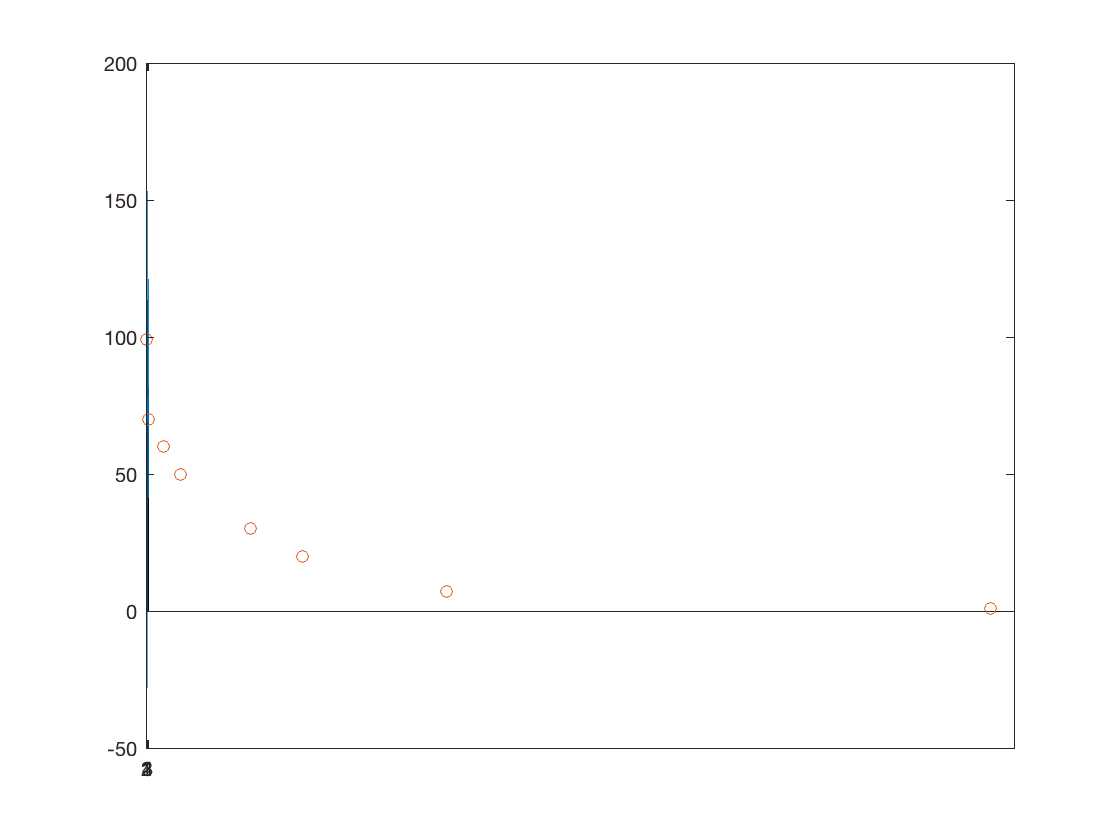

days = [1, 5, 30, 60, 180, 270, 520, 1460];
value = [99, 70, 60, 50, 30, 20, 7, 1];
plot(days, value, 'o') 

## *Model 1: exponential decay model (2 parameters, A rate and B gain)*

In Matlab, @ is for handling functions. @(params, x ) means it's a function of x with parameters "params". "Params" is an array specifying values of parameters of ProbDistParametric object

exponential_func = @(params, x) params(1) .* exp(-params(2) * x);

Define starting values for the fitting parameters (need this for fitting anything)

exp_x0 = [0 0];

Obtain parameter estimates and normalized residuals based on the data given in 'days'; and 'values'. *Lsqcurvefit* is a [nonlinear least-squares](https://en.wikipedia.org/wiki/Non-linear_least_squares) solver (meaning to fit a set of *m* observations with a model that is non-linear in *n* unknown parameters (*m* > *n*)) for finding solutions that [converge](https://en.wikipedia.org/wiki/Convergence_of_random_variables). Convergence is the idea that a sequence of random or unpredictable events can be expected to settle down into a behavior that is essentially unchanging when items far enough into the  sequence are studied. 

*x = lsqcurvefit(fun,x0,xdata,ydata) *starts at x0 and finds coefficients x to best fit the nonlinear function *fun(x,xdata)* to the data ydata (in the least-squares sense).

% Suppress verbose warnings
 options = optimset( 'Display', 'off' );

 [exp_params, exp_resnorm] = lsqcurvefit(exponential_func, exp_x0, days, value);

## *Model 2: Hyperbolic decay model (2 parameters, A rate and B gain)*

hyperbolic_func = @(params, x) params(1) ./ (1 + params(2) .* x);

Again, define starting values for the parameters

hyp_x0 = [0 0];

Perform the fitting

% Suppress verbose warnings
options = optimset( 'Display', 'off' );

[hyp_params, hyp_resnorm] = lsqcurvefit(hyperbolic_func, hyp_x0, days, value);

Plot the real data and model fits

figure;
x_vector = min(days):max(days);

%   plot the real data with symbol *
plot( days, value, 'k*' ); hold on;  

Plot the fit by using the function we made (exponential_func) with the fitted parameters "exp_params" as a function of x_vector. This can be done by *exponential_func(exp_params, x_vector)* in the Y term for the plot

plot( x_vector, exponential_func(exp_params, x_vector), 'b' );
plot( x_vector, hyperbolic_func(hyp_params, x_vector), 'r' );
legend({ 'Data', 'Exponential Fit', 'Hyperbolic Fit'} );

Let's examine normalized residuals

figure;
bar( [exp_resnorm, hyp_resnorm] );  % low residuals are better. Residuals indicate the difference between the 
% observed value and the estimated value. A low value means that the difference between the two is small, so a good fit. 
set( gca, 'xticklabels', {'Exponential', 'Hyperbolic'} );
ylabel( 'Normalized Residuals' );
xlim( [.5 2.5] );

You can see that the hyperbolic fit performs better than expected.

## Comparing the model fits to find the best model (AIC, BIC, cross-validation)

## *A. AIC and BIC*

The [Akaike Information Criterion](https://en.wikipedia.org/wiki/Akaike_information_criterion) (AIC) and [Bayesion Information Criterion](https://en.wikipedia.org/wiki/Bayesian_information_criterion) (BIC) penalizes the parameter for the lost information. 

The **AIC **is a measure of the relative quality of statistical models for a given set of data. Given a collection of models for the data, the AIC estimates the quality of each model relative to each of the other models. The AIC is founded on the [information theory](https://en.wikipedia.org/wiki/Information_theory): it offers a relative estimate of the information lost when a given model is used to represent the process that generates the data. In other words, AIC estimates for the unkown true [likelihood function](https://en.wikipedia.org/wiki/Likelihood_function) of the data and the fitted likelihood function. In doing so, it deals with the trade-off between the [goodness of fit](https://en.wikipedia.org/wiki/Goodness_of_fit) of the model and the complexity of the model.


$$AIC = 2k -2Ln(\hat{L}) $$


- $ \hat {L} $ is the mazimes value of the likelihoood function of the model M: $\hat{L} = p(x | \hat{\theta}, Model)$, where $\theta$ is parameter value that maximizes L.

- k is the number of free parameters to be estimated (taking into account the number of parameters of the model)

- x is the observed data

*Model with the minimum AIC value is the better model*

The **BIC **select models among a finite set of models, in which the model with the lowest BIC is preferred. It is based, in part, on the [likelihood function](https://en.wikipedia.org/wiki/Likelihood_function) and it is closely related to the (AIC). When fitting models, it is possible to increase the likelihood by adding parameters, but doing so may result in overfitting. Both BIC and AIC attempt to resolve this problem by introducing a *penalty term* for the number of parameters in the model; the penalty term is larger in BIC than in AIC.


$$BIC = k*ln(n) - 2ln(\hat{L})   $$
 

- $ \hat {L} $ is the maximized value of the likelihoood function of the model M: $\hat{L} = p(x | \hat{\theta}, Model)$, where $\theta$ is parameter value that maximizes L.

- x is the observed data

- n is the number of data points in x, the number of observations, or the sample size

- k is the number of free parameters to be estimated. If the model under consideration is a [linear regression](https://en.wikipedia.org/wiki/Linear_regression), k is the number of [regressors](https://en.wikipedia.org/wiki/Regressor), including the intercept

*Model with the minimum BIC value is the better model*

Difference:

BIC converges into one model with the growing number of observations (sample size). So, BIC is more conservative in picking a smaller model when the sample size is high.This means that BIC penalizes the number of parameters more compared to AIC.

AIC example: Remember that you need a likelihood function!

% R = poissrnd(lambda, m, n) generates random numbers from the Poisson distribution with mean parameter lambda. 
% m by n array
x = poissrnd(20,30,1);

% pd = fitdist(x,distname) creates a probability distribution object by fitting the distribution specified by distname 
% to the data in column vector x.
pd1 = fitdist(x,'poisson');
pd2 = fitdist(x,'normal');

% log likelihood for each model ("NlogL" field contains this info)
pd1LogL = -1*pd1.NLogL; 
pd2LogL = -1*pd2.NLogL;


Get the AIC: aic = aicbic(logL,numParam) returns AIC corresponding to the optimized log-likelihood function values (logL). The input arguments are the logL *estimate*, and the model parameters *numParam*. The output argument is the value for either AIC or BIC. For more information, look up the *aicbic* function.

numParam1=1; % poisson has 1 parameter, but normal has 2
numParam2=2;

aic = aicbic([pd1LogL, pd2LogL], [numParam1,numParam2]);
% poisson wins (lower AIC)


BIC requires the number of observations as indicated above, so let's try with different number of observations:

x = poissrnd(20,30,1);
%y = poissrnd(20,130,1);  % much larger sample -> try different number of observations -> results change!


*pd = fitdist(x,distname)* creates a probability distribution object by fitting the distribution specified by *distname* to the data in column vector x.

pd1 = fitdist(x,'poisson');
pd2 = fitdist(x,'normal');

% log likelihood for each model
pd1LogL = -1*pd1.NLogL; 
pd2LogL = -1*pd2.NLogL;

[aic bic] = aicbic([pd1LogL, pd2LogL], [numParam1,numParam2], [30,30]);
    

## *B. Cross-validation*

[Cross validation](https://en.wikipedia.org/wiki/Cross-validation_(statistics)) involves partitioning of the sample of data into the *training set *and the *validation set*, and assess how the results of a statistical analysis will generalize to an independent data set. It is mainly used in settings where the goal is prediction, and one wants to estimate how accurately a predictive model will perform in practice. In a prediction problem, a model is usually given a dataset of *known data* on which training is run (*training dataset*), and a dataset of *unknown data* (or *first seen* data) against which the model is tested (*testing dataset*). The goal of cross validation is to define a dataset to "test" the model in the training phase (*i.e.*, the validation dataset), in order to limit problems like overfitting, give an insight on how the model will generalize to an independent  dataset (*i.e.*, an unknown dataset, for instance from a real problem). Therefore, multiple rounds of cross-validation uses different partitions to average the validation over these rounds. Then, the error between the training set and the validation set is used and the model with consistently smaller errors wins.

Here, we perform cross-validation comparison (smaller *root mean square error (*RMSE) is better) to test how the results of a statistical analysis will generalize to an independent data set. We will use a "training dataset" and test it on the "tested dataset". This procedure will be performed for mutiple times (take care of noise/variability).

Using the parameters of the hyperbolic equation, let's generate a larger set of delay-discounted values:

rng( 'default' ); % for reproducibility (random number generator)

% generate a vector of days 

x = 1:1000;


Now we obtain a vector of discounted values based on the hyperbolic function and estimated hyperbolic parameters. The same function is used as above: *hyperbolic_func = @(params, x) params(1) ./ (1 + params(2) .* x)*

First, we will generate a hyperbolic data, and then we will add noise to this data to create "observed" data to test whether hyperbolic or exponential will perform better.

y = hyperbolic_func( hyp_params, x );
 
% add some NOISE to the values in y (this will generate "observed" data [for testing two models])
noise_gain = 3;
noise_index = rand( size(y) ) > .5;

% if there is 0, then replace it
noise_index = double(noise_index);
noise_index( find(noise_index==0) ) = -1;

There are many ways to define the noise-added version, this is one way. So, "y" is the data we are comparing the two models' performances.

noise = 1 ./ (1 + rand(size(noise_index))) * noise_gain;
y = y + noise_index .* noise;
% y = y + noise_index .* rand(size(noise_index)) * noise_gain;

n_partitions = 100;  % partitioning for cross-validation
partition_size = numel(y) / n_partitions;
start = 0;

For the training sample, preallocated the index of the hyperbolic or exponential function with lower mse.

hyperbolic_perfomed_better = false( size(n_partitions) );  % set up storing the outcome of the cross-validation

We use the [k-fold cross-validation](https://en.wikipedia.org/wiki/Cross-validation_(statistics)#k-fold_cross-validation) (one type of cross-validation). In *k*-fold cross-validation, the original sample is randomly partitioned into *k* equal sized subsamples. Of the *k* subsamples, a single subsample is retained as the validation data for testing the model, and the remaining *k* − 1 subsamples are used as training data. The cross-validation process is then repeated *k* times (the *folds*), with each of the *k* subsamples used exactly once as the validation data. The *k* results from the folds can then be averaged to produce a single estimation. The advantage of this method over repeated random sub-sampling is that all observations are used for both training and validation, and each observation is used for validation exactly once.

for i = 1:n_partitions  % we set it at 10 parts (so, testing 10 parts of the data)
  
  keep_index = true( size(y) );
  terminus = start + partition_size;  % for this round, first "part" of the dataset
  start = start + 1;
  keep_index( start:terminus ) = false;   % setting up indexing (1 or 0) for one set
  kept_x = x( keep_index );
  kept_y = y( keep_index );
  left_x = x( ~keep_index );
  left_y = y( ~keep_index );
  
  % STEP 1
  % Use the "kept dataset, kept_x and kept_y" to derive the model exp and hyp model parameters
  
  % Suppress verbose warnings
  options = optimset( 'Display', 'none' );
 
  exp_params = lsqcurvefit( exponential_func, exp_x0, kept_x, kept_y); 
  hyp_params = lsqcurvefit( hyperbolic_func, hyp_x0, kept_x, kept_y);
  
  % STEP 2
  % Now, how use the fit parameters based on "kept dataset" above work with "left x" to "*predict left y" 
  
  % -> The fitted values "exp_params" from the "kept datasets" (exp_parms and hyp_params) are now
  %    expressed as a function of "left_x" to "*predict left_y"
  predicted_y_exp = exponential_func( exp_params, left_x );
  predicted_y_hyp = hyperbolic_func( hyp_params, left_x );

  % STEP 3
  % You have real "left y" and "predicted left y" from the model parameters based on the kept dataset ("kept_x" and "kept_y")
  
  % Get mean of the squared errors for each model: 1) predicted_y from the model constructed 
  % From the "kept dataset" VS. 2) true y of the "left dataset, left_y"
  mse_exp = mean( (predicted_y_exp - left_y).^2 );
  mse_hyp = mean( (predicted_y_hyp - left_y).^2 );
  
  % now compare the model and save the outcome
  hyperbolic_perfomed_better(i) = mse_hyp < mse_exp;
  
  % start from where we left off and go to the next "part" of the data
  start = terminus;
  
end

p = 1 - sum(hyperbolic_perfomed_better) / n_partitions;

disp( p );

Unexpected MATLAB expression.